# 本段代码用来计算类GHZ态的集体导引范围

改变类GHZ态参数，遍历所有测量方向，并保存SetⅠⅡ共计6个不等式的最大值和对应测量方向

phi：GHZ态参数

Phi：测量方向参数1

Theta：测量方向参数2

value：不等式的最大值

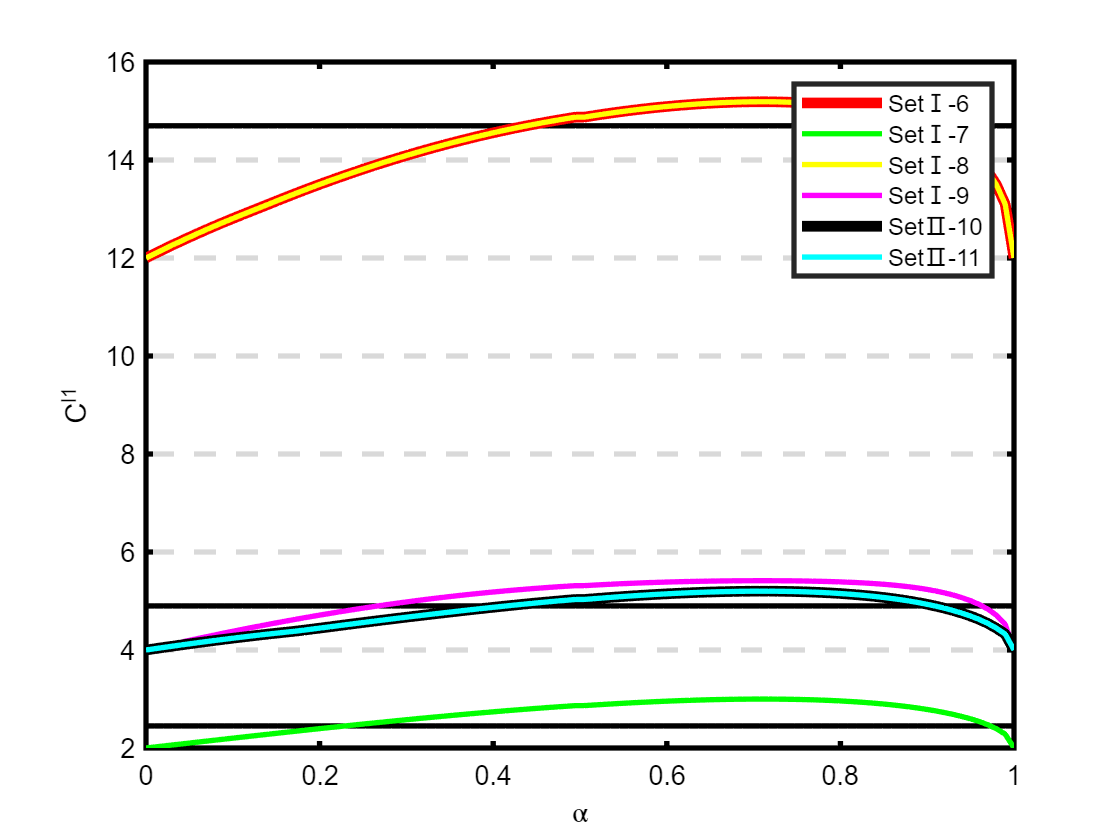

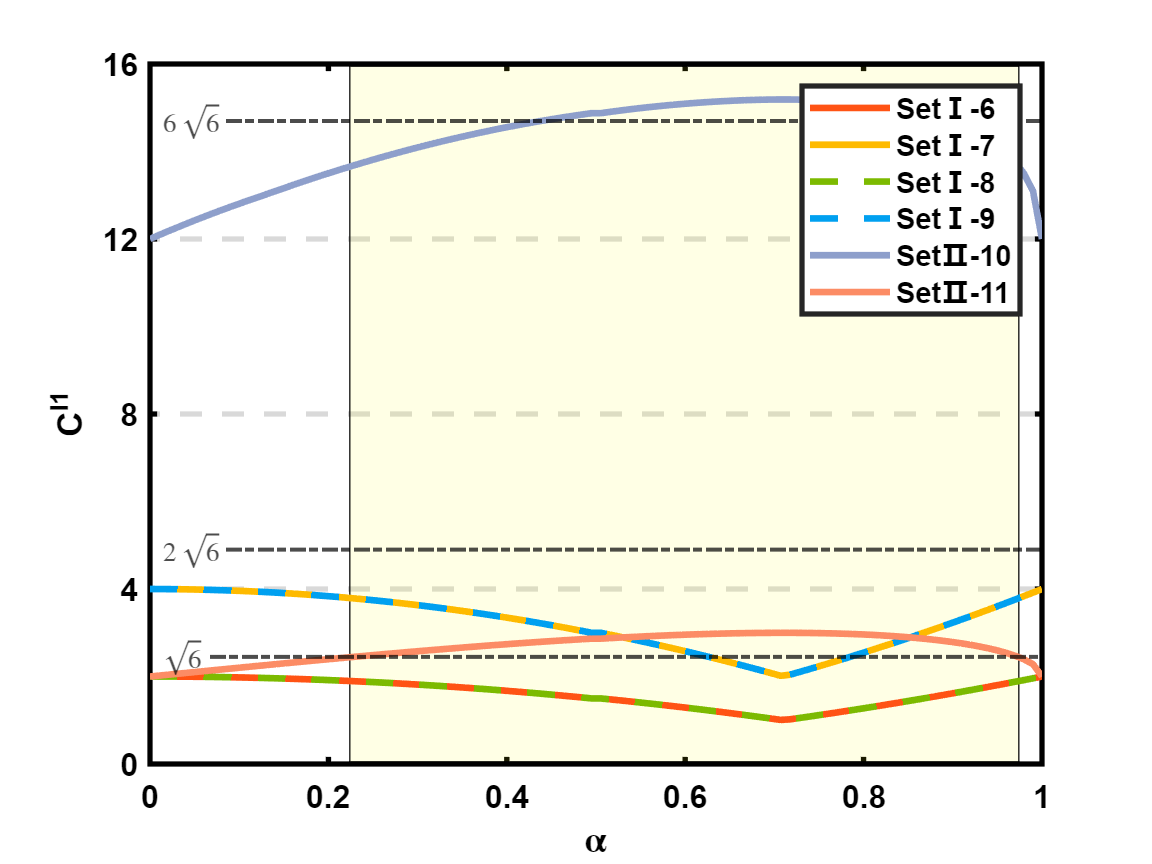

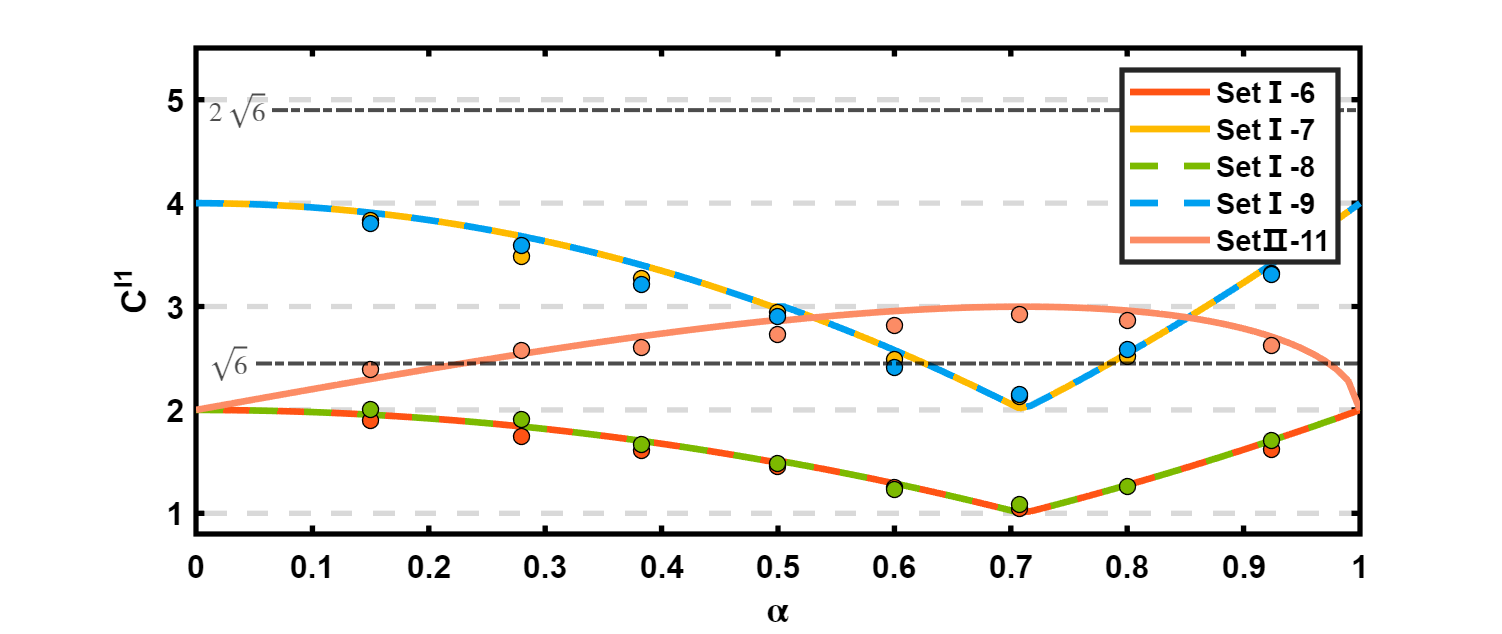

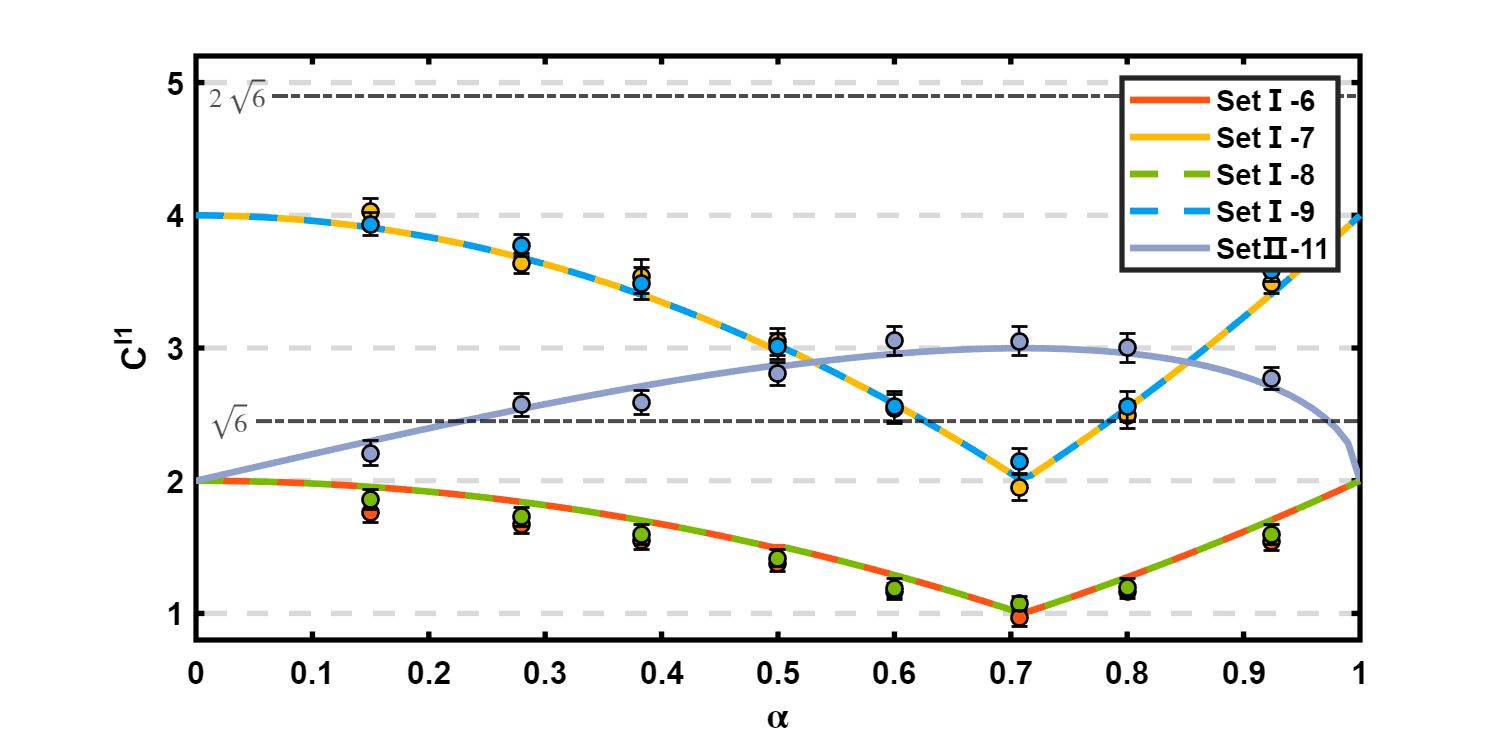

Set2_Charlie1 =     1.0000    1.0000    1.7000    1.6700



Set2_Charlie1 =

     []



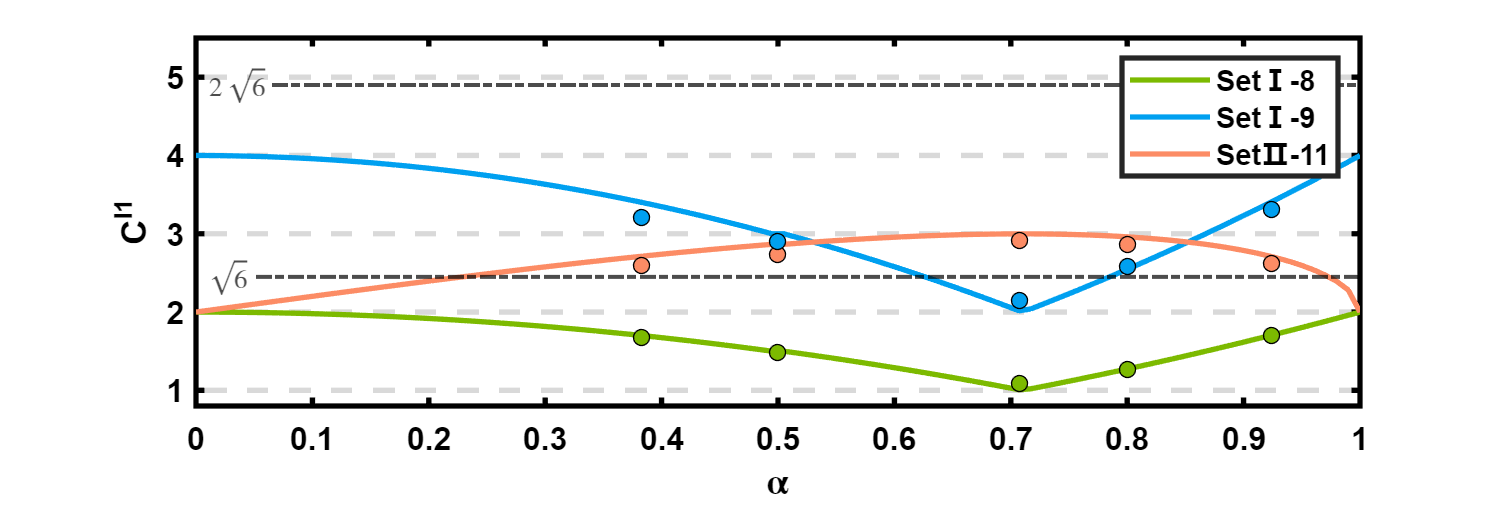

clc
clear;
close all;

H = [1,0]';
V = [0,1]';

phi = linspace(0,1,100);
value = zeros(10,length(phi));
Theta = zeros(10,length(phi));
Phi = zeros(10,length(phi));

for i = 1:length(phi)
    a = phi(i);
    GHZ = a*kron(kron(H,H),H)+sqrt(1-a^2)*kron(kron(V,V),V);
    rho = GHZ*GHZ';

    [value(1,i),Theta(1,i),Phi(1,i)] = find_direction1(rho);
    [value(2,i),Theta(2,i),Phi(2,i)] = find_direction2(rho);
    [value(3,i),Theta(3,i),Phi(3,i)] = find_direction3(rho);
    [value(4,i),Theta(4,i),Phi(4,i)] = find_direction4(rho);
    [value(5,i),Theta(5,i),Phi(5,i)] = find_direction5(rho);
    [value(6,i),Theta(6,i),Phi(6,i)] = find_direction6(rho);
    i
end
save value
save Theta
save Phi